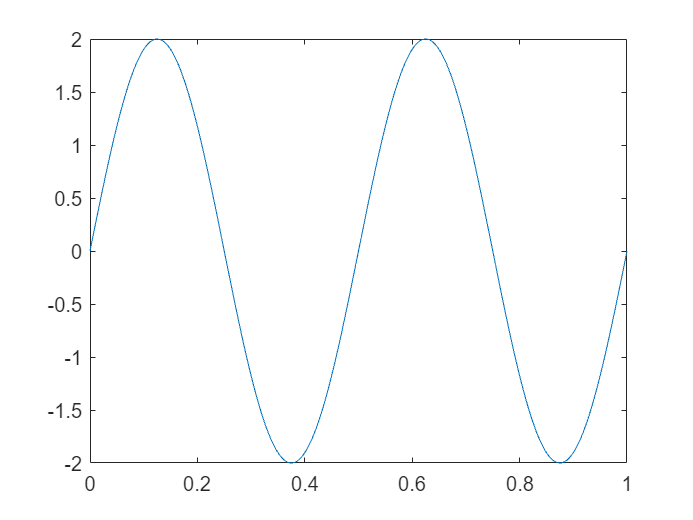

%# A x(t) = 2 sin (4 pi t)
% frequencia = 2
% periodo = 0.5
% max = 2
ts = 0.001;
t0 = 0;
t = t0:ts:1;
xt = 2*sin(4*pi*t);
plot(t,xt)

potencia_sinais(xt,0.001,0.5)

ans = 2

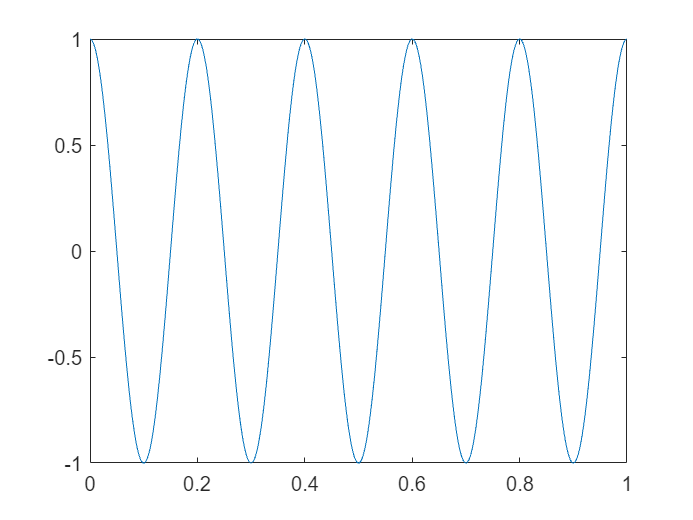

%# B x(t) = sin (10 pi t + pi/2)
% frequencia = 5
% periodo = 0.2
% max = 1
ts = 0.001;
t0 = 0;
t = t0:ts:1;
xt = sin(10*pi*t + pi/2);
plot(t,xt)

potencia_sinais(xt,0.001,0.2)

ans = 0.5000

%# C x(t) = sin (20*pi*t + 70*pi/180) + sin(20*pi*t + 200*pi/180)
% frequencia = 10
% periodo = 0.1
% max = 2
ts = 0.001;
t0 = 0;
t = t0:ts:0.5;
xt = sin(20*pi*t + 70*pi/180) + sin(20*pi*t + 200*pi/180);
max(xt)

ans = 0.8448

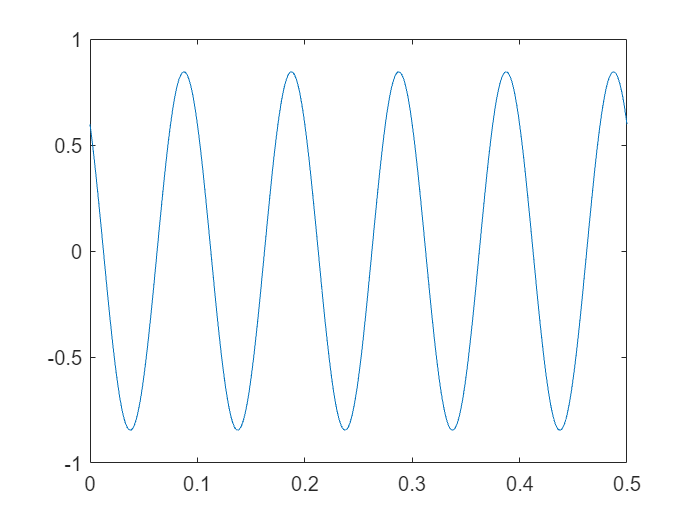

plot(t,xt)
potencia_sinais(xt,0.001,0.1)

%# D x(t) = sin(6𝜋𝑡) + sin(8𝜋𝑡)
% frequencia = 1 (maximo divisor comum das frequencias (3 e 4))
% periodo = 1

ts = 0.001;
t0 = 0;
t = t0:ts:2;
xt = sin(6*pi*t)+sin(8*pi*t)

xt =          0    0.0440    0.0879    0.1318    0.1757    0.2194    0.2631    0.3066    0.3499    0.3931    0.4361    0.4788    0.5213    0.5635    0.6055    0.6471    0.6884    0.7294    0.7699    0.8101    0.8499    0.8892    0.9281    0.9665    1.0044    1.0418    1.0786    1.1149    1.1507    1.1858    1.2204    1.2543    1.2876    1.3202    1.3522    1.3834    1.4140    1.4438    1.4729    1.5013    1.5289    1.5557    1.5817    1.6069    1.6314    1.6549    1.6777    1.6996    1.7206    1.7408


x1 = sin(6*pi*t);
x2 = sin(8*pi*t);
max(xt)

ans = 1.9509

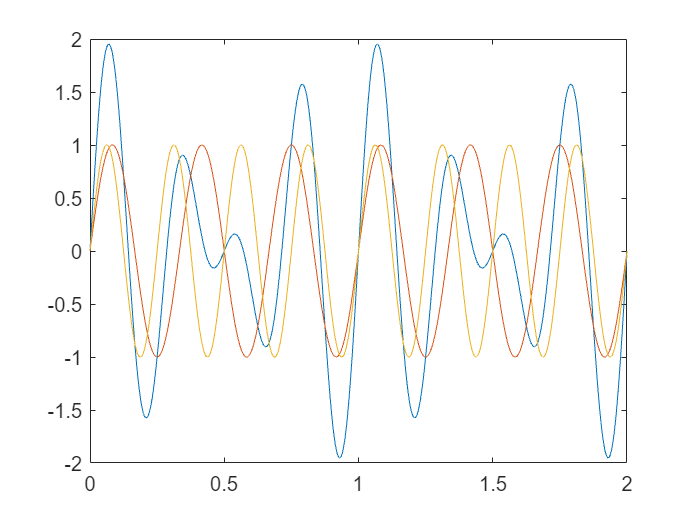


potencia_sinais(xt,0.001,1)
plot(t,xt)
hold on 
plot(t,x1)
plot(t,x2)
hold off

%# E x(t) = sin(6𝜋𝑡) + sin(8𝜋𝑡 + 0.1)
% frequencia = 1 (igual ao anterior)
% periodo = 1
% max = 2
ts = 0.001;
t0 = 0;
t = t0:ts:4;
xt = sin(6*pi*t)+sin(8*pi*t + 0.1);
max(xt)

ans = 1.9304

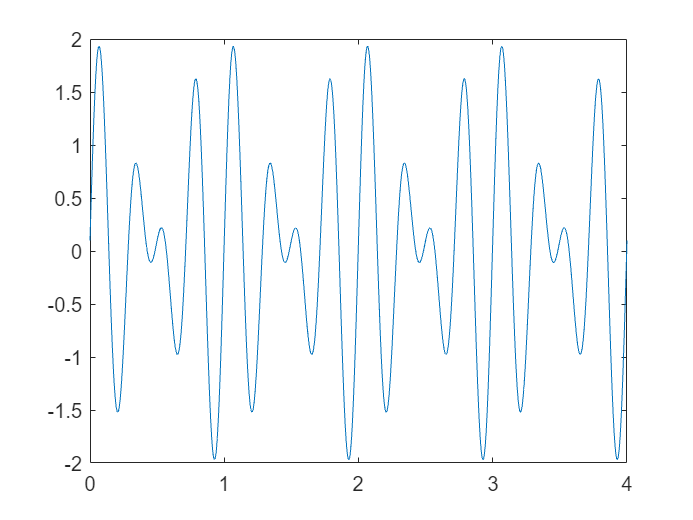

potencia_sinais(xt,0.001,4)
plot(t,xt)

%# F x(t) = sin(6𝜋𝑡) + sin(7𝜋𝑡) + sin(8𝜋𝑡)
% frequencia = 0.5 (maximo divisor comum entre )
% periodo = 2
ts = 0.001;
t0 = 0;
t = t0:ts:4;
xt = sin(6*pi*t)+sin(8*pi*t)+sin(7*pi*t);
freq = gcd(gcd(6,7),8)/2

freq = 0.5000

max(xt)

ans = 2.9504

potencia_sinais(xt,ts,2)

ans = 1.5000

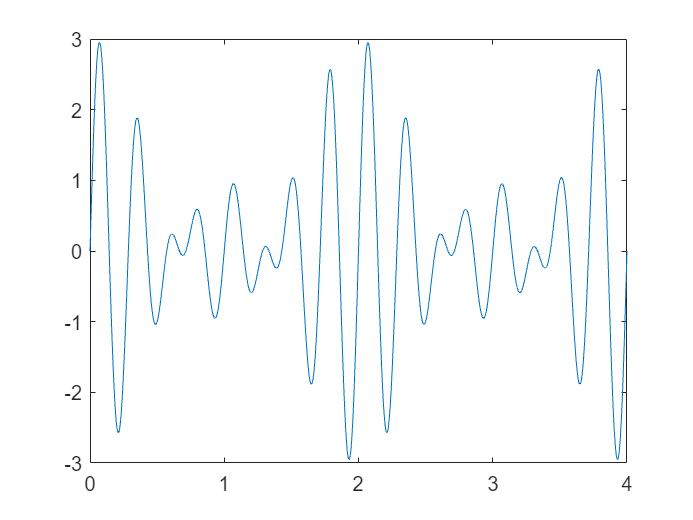

plot(t,xt)

% 2. Quando as frequencias tem casas decimais, multiplicar por uma
% constante e depois dividir o maximo divisor comum por essa constante para
% obter o f0.

% 3. Esta adicionado nos exercicios 1.

% 4. 
t0 = 0

t0 = 0

ts = 0.0001

ts = 1.0000e-04

t = t0:ts:1

t =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


a1 = sin(20*pi*t + (rand()*2*pi) - pi);
a2 = sin(40*pi*t + (rand()*2*pi) - pi);
a3 = sin(60*pi*t + (rand()*2*pi) - pi);
a = a1 + a2 + a3;
f = gcd(gcd(10,20),30);
T = 1/f;
maxim = max(a);
potencia_sinais(a,0.0001,T)

ans = 1.5000

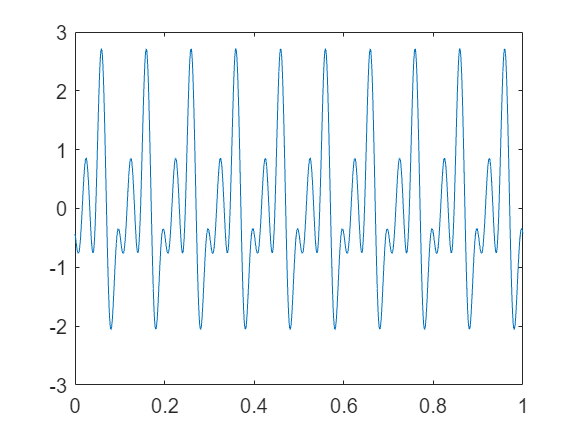

plot(t,a)